# Analyse properties of conserved moieties

tutorial_initConservedMoietyPaths

projectDir = '~/work/sbgCloud/programExperimental/projects/tracerBased'

dataDir = '~/work/sbgCloud/programExperimental/projects/tracerBased/data/'

softwareDir = '~/work/sbgCloud/programExperimental/projects/tracerBased/software/'

visDataDir = '~/work/sbgCloud/programExperimental/projects/tracerBased/data/visualisation/'

resultsDir = '~/work/sbgCloud/programExperimental/projects/tracerBased/results/iDopaNeuroCT_ConservedMoieties/'

rxnfileDir = '~/work/sbgCloud/code/fork-ctf/modelDatabases/iDNct/rxns/atomMapped'

if ~recompute
    load([resultsDir  modelName '_ConservedMoietiesAnalysis.mat'])
    return
end

Load the atomically resolved models derived from identifyConservedMoieties.m

load([resultsDir modelName '_arm.mat'])

Basic properties of atomically resolved models

disp(arm)

     MRH: [1×1 struct]
    dATM: [1×1 digraph]
    M2Ai: [1549×71424 double]
    Ti2R: [139894×2034 double]
    Ti2I: [139894×221 double]
     ATG: [1×1 graph]
     M2A: [1549×71424 double]
     A2R: [82764×2034 double]
    A2Ti: [82764×139894 double]
     I2A: [221×71424 double]
     A2I: [82764×221 double]
     I2C: [221×5668 double]
     C2A: [5668×71424 double]
     A2C: [82764×5668 double]
     MTG: [1×1 graph]
     I2M: [221×47717 double]
     M2I: [61215×221 double]
     M2M: [1549×47717 double]
     M2R: [61215×2034 double]
       L: [221×1549 double]



Load the model, unless it is also saved with the results.

if 0
    load([dataDir modelName '.mat'])
    model = iDopaNeuro;
else
    model=arm.MRH;
end

Identify the stoichiometrically consistent subset of the model

massBalanceCheck=0;
printLevel=1;
[SConsistentMetBool, SConsistentRxnBool1, SInConsistentMetBool, SInConsistentRxnBool, unknownSConsistencyMetBool, unknownSConsistencyRxnBool, model]...
    = findStoichConsistentSubset(model,massBalanceCheck,printLevel);

--- findStoichConsistentSubset START ----
--- Summary of stoichiometric consistency ----
  1569	  2491	 totals.
     0	   322	 heuristically external.
  1569	  2169	 heuristically internal:
  1569	  2168	 ... of which are stoichiometrically consistent.
     0	     0	 ... of which are stoichiometrically inconsistent.
     0	     1	 ... of which are of unknown consistency.
  1569	  2168	 Confirmed stoichiometrically consistent by leak/siphon testing.
--- findStoichConsistentSubset END ----


Remove non-atom mapped part of the model, but keep the external reactions

keepRxnBool = getCorrespondingCols(arm.MRH.S, arm.MRH.metAtomMappedBool, true(size(arm.MRH.S,2),1), 'inclusive');
keepRxnBool = keepRxnBool & ~SConsistentRxnBool1;
removeRxnBool = ~(arm.MRH.rxnAtomMappedBool | keepRxnBool);
model = removeRxns(arm.MRH, arm.MRH.rxns(removeRxnBool));

2 model.C constraints removed


Identify the stoichiometrically consistent subset of the model

massBalanceCheck=1;
printLevel=1;
[SConsistentMetBool, SConsistentRxnBool2, SInConsistentMetBool, SInConsistentRxnBool, unknownSConsistencyMetBool, unknownSConsistencyRxnBool, model]...
    = findStoichConsistentSubset(model,massBalanceCheck,printLevel);

--- findStoichConsistentSubset START ----
--- Summary of stoichiometric consistency ----
  1549	  2356	 totals.
     0	   321	 heuristically external.
  1549	  2035	 heuristically internal:
  1549	  2034	 ... of which are stoichiometrically consistent.
     0	     0	 ... of which are stoichiometrically inconsistent.
     0	     1	 ... of which are of unknown consistency.
---
     0	     1	 heuristically internal and stoichiometrically inconsistent or unknown consistency.
     4	     1	 ... of which are elementally imbalanced (inclusively involved metabolite).
     0	     1	 ... of which are elementally imbalanced (exclusively involved metabolite).
  1549	  2034	 Confirmed stoichiometrically consistent by leak/siphon testing.
--- findStoichConsistentSubset END ----


Table of model properties

rankN=getRankLUSOL(arm.MRH.S(arm.MRH.metAtomMappedBool,arm.MRH.rxnAtomMappedBool));
rankL=getRankLUSOL(arm.L);
rankdATM=getRankLUSOL(incidence(arm.dATM));
rankATG=getRankLUSOL(incidence(arm.ATG));
rankMTG=getRankLUSOL(incidence(arm.MTG));

TT={'Model', 'm+'  , 'Metabolites', size(arm.MRH.S,1);
       ''     , 'm'   , 'Mapped metabolites', nnz(arm.MRH.metAtomMappedBool);
   ''     , 'n+'  , 'Reactions', size(arm.MRH.S,2);
   ''     , ''    ,  'Internal reactions', nnz(SConsistentRxnBool1);
   ''     , ''    ,  'External reactions', nnz(~SConsistentRxnBool1);
   ''     , 'n'   , 'Mapped reactions', nnz(arm.MRH.rxnAtomMappedBool);
   'Mapped model'     , 'm'   , 'size(model.S,1)', rankN;
   ''     , 'n+k'   , 'size(model.S,2)', size(model.S,2);
   ''     , ''    ,  'Internal reactions', nnz(SConsistentRxnBool2);
   ''     , ''    ,  'External reactions', nnz(~SConsistentRxnBool2);
   ''     , 'r'   , 'Rank(N)', rankN;
   ''     , 'm-r' , 'Row rank deficiency(N)', nnz(arm.MRH.metAtomMappedBool) - rankN;
   ''     , ''    ,  'Isomorphism classes', size(arm.L,1); 
   ''     , ''    ,  'Independent isomorphism classes', rankL; 
   'MTG'  , ''    ,  'Moieties', size(arm.I2M,2); 
   ''     , ''    ,  'Moiety transitions', size(arm.M2I,1); 
   ''     , ''    ,  'Rank(M)', rankMTG; 
  'ATG'   , ''    ,  'Atoms', size(arm.I2A,2); 
   ''     , ''    ,  'Atom transitions', size(arm.A2I,1); 
   ''     , ''    ,  'Rank(A)', rankATG; 
   ''     , ''    ,  'Row rank deficiency(A)', size(arm.I2A,2) - rankATG;
   ''     , ''    ,  'Components', size(arm.C2A,1); 
'dATM'    , ''    ,  'Atoms', size(arm.dATM.Nodes,1); 
   ''     , ''    ,  'Directed atom transition instances', size(arm.dATM.Edges,1); 
   ''     , ''    ,  'Rank(dATM)', rankdATM; 
   ''     , ''    ,  'Row rank deficiency(dATM)', size(arm.dATM.Edges,1) - rankdATM;
   ''     , ''    ,  '', NaN;  
   };
disp(TT)

    {'Model'       }    {'m+'    }    {'Metabolites'               }    {[  1569]}
    {0×0 char      }    {'m'     }    {'Mapped metabolites'        }    {[  1549]}
    {0×0 char      }    {'n+'    }    {'Reactions'                 }    {[  2491]}
    {0×0 char      }    {0×0 char}    {'Internal reactions'        }    {[  2168]}
    {0×0 char      }    {0×0 char}    {'External reactions'        }    {[   323]}
    {0×0 char      }    {'n'     }    {'Mapped reactions'          }    {[  2034]}
    {'Mapped model'}    {'m'     }    {'size(model.S,1)'           }    {[  1406]}
    {0×0 char      }    {'n+k'   }    {'size(model.S,2)'           }    {[  2356]}
    {0×0 char      }    {0×0 char}    {'Internal reactions'        }    {[  2034]}
    {0×0 char      }    {0×0 char}    {'External reactions'        }    {[   322]}
    {0×0 char      }    {'r'     }    {'Rank(N)'                   }    {[  1406]}
    {0×0 char      }    {'m-r'   }    {'Row rank deficiency(N)'    }    {[   143]}
    

## Properties of conserved moieties

[moietyMasses, knownmoietyMasses, unknownElements, Ematrix, elements] = getMolecularMass(moietyFormulae);
[metMasses, knownmetMasses, unknownElements, Ematrix, elements] = getMolecularMass(model.metFormulas);

Compare the distributions of the molecular moietyMasses

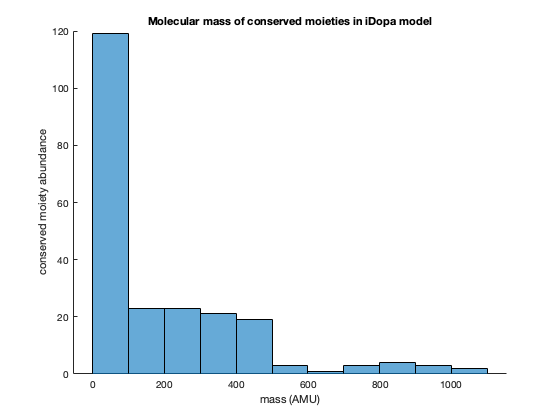

figure
hold on
h = histogram(moietyMasses);
xlabel('mass (AMU)')
ylabel('conserved moiety abundance')
title('Molecular mass of conserved moieties in iDopa model')

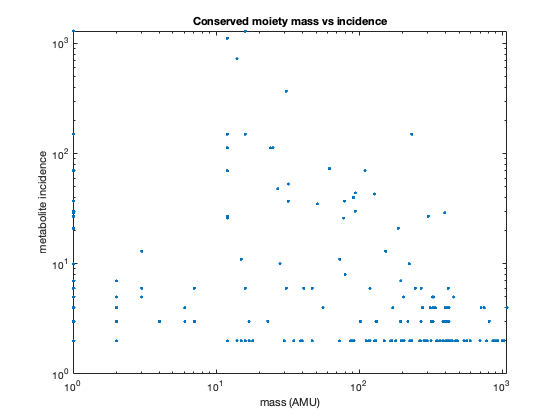

%h2.BinWidth = 0.25;
figure
moietyIncidence = sum(arm.L~=0,2);
loglog(moietyMasses,moietyIncidence,'.')
title('Conserved moiety mass vs incidence')
xlabel('mass (AMU)')
ylabel('metabolite incidence')

The metabolite mass vs mass weighted incidence of moieties in each metabolite should be a straight line trough the origin if all of the moieties that make up a metabolite are present and the formula for the metabolite is correct. Sometimes the metabolite formula is ambiguous, e.g., FULLR in the formula, so the mass will be incorrect.

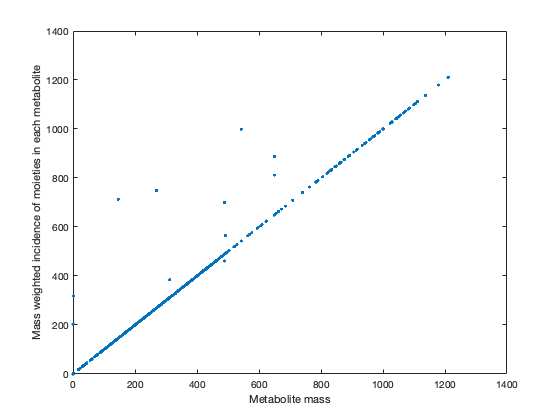

figure
approxMetMasses = arm.L'*moietyMasses;
plot(metMasses,approxMetMasses,'.')
xlabel('Metabolite mass')
ylabel('Mass weighted incidence of moieties in each metabolite')

massDifference = abs(approxMetMasses-metMasses)./metMasses;
bool=massDifference >0.1;
n=1;
C = cell(nnz(bool),6);
for i=1:size(model.S,1)
    if bool(i)
        C(n,:)={i, massDifference(i),model.mets{i},model.metFormulas{i},metMasses(i),approxMetMasses(i)};
        n=n+1;
    end
end
C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','massDifference','mets','metFormula','metMass','approxMetMass'};
disp(T)

    index    massDifference            mets                      metFormula               metMass    approxMetMass
    _____    ______________    ____________________    _______________________________    _______    _____________

     123        0.24803        {'galgluside_hs[c]'}    {'C30H56NO12FULLRCO'          }    650.38        811.69    
     524         0.3648        {'digalside_hs[c]' }    {'C30H56NO12FULLRCO'          }    650.38        887.63    
     525         0.3648        {'digalside_hs[l]' }    {'C30H56NO12FULLRCO'          }    650.38        887.63    
     667        0.24803        {'galgluside_hs[l]'}    {'C30H56NO12FULLRCO'          }    650.38        811.69    
    1497        0.24803        {'galgluside_hs[r]'}    {'C30H56NO12FULLRCO'          }    650.38        8

Metabolites with mass most similar to the mass of the moiety they contain

[minimalMassMetabolite, minimalMassFraction, numMinimalMassMetabolites] = representativeMolecule(arm.L,moietyFormulae,model.mets);
if ~isfield(model,'metNames')
    model.metNames = model.mets;
end

## High molecular weight moieties that are present in many metabolites.

massWeightedIncidence=diag(moietyMasses)*arm.L*ones(size(arm.L,2),1);
[massWeightedIncidenceSorted, xi] = sort(massWeightedIncidence,'descend');
bool=false(size(arm.L,1),1);
bool(xi(1:min(length(xi),30)))=1;
C = cell(nnz(bool),9);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Minimalmassmetabolite','Name','Formula','Massfraction'};
size(T,1)

ans = 30

disp(T)

    index    metabolites    rxns     moietyformula       mass     Minimalmassmetabolite                  Name                             Formula                Massfraction
    _____    ___________    ____    ________________    ______    _____________________    ________________________________    ______________________________    ____________

      46           4           6    {'C44H48N12O21'}    1080.3    {'6dhf[c]'         }     {'Hexaglutamyl Folate (Dhf)'   }    {'C44H49N12O21'              }       0.99907  
     109           3           4    {'C48H93NO8'   }    811.69    {'galgluside_hs[c]'}     {'Galactosyl Glucosyl Ceramide'}    {'C30H56NO12FULLRCO'         }             1

## Moieties that are present in a near maximal number of metabolites.

bool=moietyIncidence>=100;
C = cell(nnz(bool),9);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,2,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Minimalmassmetabolite','Name','Formula','Massfraction'};
size(T,1)

ans = 18

disp(T)

    index    metabolites    rxns    moietyformula      mass     Minimalmassmetabolite             Name                  Formula          Massfraction
    _____    ___________    ____    ______________    ______    _____________________    ______________________    __________________    ____________

      1         1297        7258    {'H'         }    1.0078        {'h[m]'     }        {'Proton'            }    {'H'             }             1  
      2         1288        6481    {'O'         }    15.995        {'h2o[c]'   }        {'Water'             }    {'H2O'           }       0.88809  
      3         1113        5150    {'C'         }        12        {'co2[m]'   }        {'Ca

## Moieties that are present in a moderate number of metabolites.

bool= moietyIncidence>=10 & moietyIncidence<=100;
C = cell(nnz(bool),9);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,9,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Minimalmassmetabolite','Name','Formula','Massfraction'};
size(T,1)

ans = 45

disp(T)

    index    metabolites    rxns    moietyformula     mass     Minimalmassmetabolite                       Name                                 Formula               Massfraction
    _____    ___________    ____    _____________    ______    _____________________    __________________________________________    ____________________________    ____________

      30         53         206     {'S'        }    31.972       {'HC00250[e]' }       {'Hydrosulfide'                          }    {'HS'                      }       0.96944  
      70         10          42     {'C9H10N3O4'}    224.07       {'cytd[c]'    }       {'Cytidine'                              }    {'C9H13N3O5'          

## Moieties that are present in a small number of metabolites.

bool= moietyIncidence>2 & moietyIncidence<=10;
C = cell(nnz(bool),9);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Minimalmassmetabolite','Name','Formula','Massfraction'};
size(T,1)

ans = 74

disp(T)

    index    metabolites    rxns      moietyformula       mass     Minimalmassmetabolite                               Name                                          Formula                Massfraction
    _____    ___________    ____    _________________    ______    _____________________    __________________________________________________________    ______________________________    ____________

      46          4           6     {'C44H48N12O21' }    1080.3    {'6dhf[c]'         }     {'Hexaglutamyl Folate (Dhf)'                             }    {'C44H49N12O21'              }       0.99907  
     109          3           4     {'C48H93NO8'    }    811.69    {'galgluside_hs[c]'}   

## Moieties that are present in a minimal number of metabolites.

bool=moietyIncidence==2;
C = cell(nnz(bool),11);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(arm.L(i,:)~=0);
        C(n,1:11) = {i,moietyFormulae{i},moietyMasses(i),model.mets{ind(1)},model.metNames{ind(1)},model.metFormulas{ind(1)},model.mets{ind(2)},model.metNames{ind(2)},model.metFormulas{ind(2)},minimalMassMetabolite{i},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,3,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','moietyformula','mass','met1','name1','formula1','met2','name2','formula2','Minimalmassmetabolite','Massfraction'};
size(T,1)

ans = 87

disp(T)

    index      moietyformula        mass             met1                                                     name1                                                        formula1                        met2                                                    name2                                                        formula2                Minimalmassmetabolite    Massfraction
    _____    __________________    ______    _____________________    ______________________________________________________________________________________    _______________________________    ____________________    _____________________________________________________________________________________

## Classification of conserved moieties

moietyTypes = classifyMoieties(arm.L, model.S);

An 'Internal' moiety is one that either does not participate in any exchange reaction or is conserved by all exchange reactions

isInternalMoiety = strcmp('Internal',moietyTypes);
bool = isInternalMoiety;
C = cell(nnz(bool),8);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(arm.L(i,:)~=0);
        C(n,1:8) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),model.mets{ind(1)},model.metNames{ind(1)},model.metFormulas{ind(1)}};
        n=n+1;
    end
end

C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Examplemet','Examplename','Exampleformula'};
size(T,1)

ans = 147

disp(T)

    index    metabolites    rxns      moietyformula        mass          Examplemet                                               Examplename                                                  Exampleformula         
    _____    ___________    ____    __________________    ______    _____________________    ______________________________________________________________________________________    _______________________________

      46           4          6     {'C44H48N12O21'  }    1080.3    {'6dhf[c]'          }    {'Hexaglutamyl Folate (Dhf)'                                                         }    {'C44H49N12O21'               }
     145           2          4     {'C39H64N7O17P3S'}    1027.3    {'phytcoa[c]' 

### A 'Transitive' moiety is one that is only found in primary metabolites

isTransititiveMoiety= strcmp('Transitive',moietyTypes);
bool = isTransititiveMoiety;
C = cell(nnz(bool),9);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,9,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Minimalmassmetabolite','Name','Formula','Massfraction'};
size(T,1)

ans = 42

disp(T)

    index    metabolites    rxns     moietyformula      mass     Minimalmassmetabolite                    Name                               Formula                Massfraction
    _____    ___________    ____    _______________    ______    _____________________    ____________________________________    ______________________________    ____________

      51           5         13     {'C9H18NO4'   }    204.12       {'acrn[c]'    }       {'O-Acetylcarnitine'               }    {'C9H17NO4'                  }             1  
      53           4          8     {'C21H30O2'   }    314.22       {'prgstrn[c]' }       {'Progesterone'                    }    {'C21H30O2'                  }  

### An 'Integrative' moiety is one that is not conserved in the open network and found in both primary and secondary metabolites.

bool= strcmp('Integrative',moietyTypes);
C = cell(nnz(bool),8);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(arm.L(i,:)~=0);
        C(n,1:8) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),model.mets{ind(1)},model.metNames{ind(1)},model.metFormulas{ind(1)}};
        n=n+1;
    end
end

C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Examplemet','Examplename','Exampleformula'};
size(T,1)

ans = 32

disp(T)

    index    metabolites    rxns    moietyformula     mass          Examplemet                                 Examplename                              Exampleformula   
    _____    ___________    ____    _____________    ______    _____________________    _________________________________________________________    ____________________

      32          27          91    {'C25H5'   }     305.04    {'7dhchsterol[r]'   }    {'Cholesta-5,7-Dien-3Beta-Ol'                           }    {'C27H44O'         }
      61           6          13    {'C18H25NO'}     271.19    {'crm_hs[l]'        }    {'N-Acylsphingosine'                                    }    {'C18H36NO2FULLRCO'}
      54          70         303    {'C4NO3'   

## Mitochondrially localised moieties

[compartments, uniqueCompartments] = getCompartment(model.mets);
isMitochondrial=strcmp('m',compartments);
nnz(isMitochondrial)

ans = 265

isCompletelyMitochondrialMoiety = ~any(arm.L(:,~isMitochondrial),2);
nnz(isCompletelyMitochondrialMoiety)

ans = 20

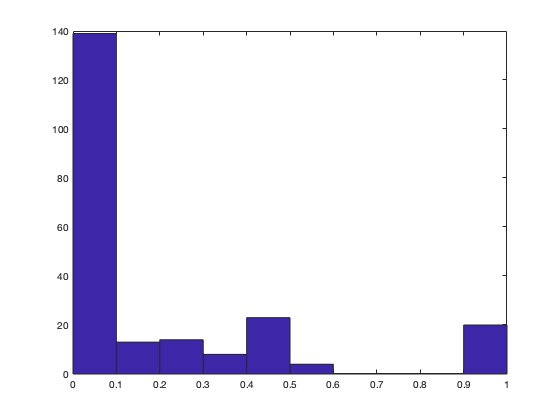

mitochondrialMoietyFraction = sum(arm.L(:,isMitochondrial),2)./sum(arm.L,2);
figure;
title('Fraction of moiety incidence that is mitochondrial')
hist(mitochondrialMoietyFraction)

bool= mitochondrialMoietyFraction==1;
C = cell(nnz(bool),8);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(arm.L(i,:)~=0);
        C(n,1:8) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),model.mets{ind(1)},model.metNames{ind(1)},model.metFormulas{ind(1)}};
        n=n+1;
    end
end

C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Examplemet','Examplename','Exampleformula'};
size(T,1)

ans = 20

disp(T)

    index    metabolites    rxns      moietyformula       mass          Examplemet                                 Examplename                              Exampleformula  
    _____    ___________    ____    _________________    ______    _____________________    __________________________________________________________    __________________

     102          2          14     {'C59H88O4'     }    860.67    {'q10[m]'           }    {'Ubiquinone-10'                                         }    {'C59H90O4'      }
      48          2          52     {'C27H24N9O15P2'}    776.09    {'fad[m]'           }    {'Flavin Adenine Dinucleotide Oxidized'                  }    {'C27H31N9O15P2' }
     131          2           2    

### Transitive moiety, of sufficient mass, with moderate incidence

isTransititiveMoiety= strcmp('Transitive',moietyTypes);
isModerateIncidence = moietyIncidence>=7 & moietyIncidence<=100;
isSufficientMass = moietyMasses > 2;
isSufficientMinimalMassFraction = minimalMassFraction > 0.1;
bool = isTransititiveMoiety & isModerateIncidence & isSufficientMass & isSufficientMinimalMassFraction;
C = cell(nnz(bool),9);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,9,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Minimalmassmetabolite','Name','Formula','Massfraction'};
size(T,1)

ans = 14

disp(T)

    index    metabolites    rxns    moietyformula     mass     Minimalmassmetabolite                Name                          Formula               Massfraction
    _____    ___________    ____    _____________    ______    _____________________    ____________________________    ____________________________    ____________

      30         53         206     {'S'        }    31.972       {'HC00250[e]' }       {'Hydrosulfide'            }    {'HS'                      }      0.96944   
     111          7          17     {'C8H6NOS2' }    195.99       {'lpam[m]'    }       {'Lipoamide'               }    {'C8H15NOS2'               }      0.95577   
      70         10          42  

## Individual moiety subnetwork

Examine the metabolites and reactions in an individual moiety subnetwork.

ind = min(size(arm.L,1),32);% anth moiety
mBool=arm.L(ind,:)~=0;
nnz(mBool)

ans = 27

rBool = getCorrespondingCols(model.S, mBool, true(size(model.S,2),1), 'inclusive');
nnz(rBool)

ans = 46

Metabolites

bool=mBool;
C = cell(nnz(bool),5);
n=1;
for i=1:size(model.S,1)
    if bool(i)
        C(n,1:5) = {i,model.mets{i},model.metNames{i},model.metFormulas{i},metMasses(i)};
        n=n+1;
    end
end
C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','met','name','formula','mass'};
disp(T)

    index           met                                       name                                   formula        mass 
    _____    __________________    ___________________________________________________________    _____________    ______

    1532     {'M01491[r]'     }    {'Cholest-5-En-3Beta-Yl Docosanoate'                      }    {'C49H88O2' }    708.68
     988     {'HC02027[r]'    }    {'Cholest-5-En-3Beta-Yl (5Z,8Z,11Z,14Z-Eicosatetraenoate)'}    {'C47H76O2' }    672.58
     985     {'HC02023[r]'    }    {'Cholest-5-En-3B-Yl (9Z-Octadecenoate)'                  }    {'C45H78O2' }     650.6
     986     {'HC02024[r]'    }    {'Cholest-5-En-3Beta-Yl (9Z,12Z-Octadecadienoate)'        }    {'C45H76O2' }    648.58
     981     {'HC02020[r]'    }    {'Cholest-5-En-3Beta-Yl Hexadecanoate'                    }   

Reactions

formulas = printRxnFormula(model, model.rxns(rBool));

7DHCHSTEROLtr	7dhchsterol[r] 	<=>	7dhchsterol[c] 
C3STKR2r	h[r] + nadph[r] + zym_int2[r] 	->	nadp[r] + zymst[r] 
C4STMO2r	o2[r] + 4mzym_int2[r] + nad[r] 	->	h[r] + co2[r] + nadh[r] + zym_int2[r] 
CHSTEROLt1	chsterol[l] 	<=>	chsterol[m] 
CHSTEROLt2	chsterol[r] 	<=>	chsterol[m] 
CHSTEROLt3	chsterol[c] 	<=>	chsterol[m] 
DHCR241r	zymst[r] + fadh2[r] 	->	fad[r] + zymstnl[r] 
DHCR242r	fadh2[r] + chlstol[r] 	->	fad[r] + lthstrl[r] 
DHCR243r	fadh2[r] + dsmsterol[r] 	->	chsterol[r] + fad[r] 
DHCR71r	h[r] + nadph[r] + ddsmsterol[r] 	->	nadp[r] + dsmsterol[r] 
DHCR72r	7dhchsterol[r] + h[r] + nadph[r] 	->	nadp[r] + chsterol[r] 
EBP1r	zymst[r] 	->	chlstol[r] 
EBP2r	zymstnl[r] 	->	lthstrl[r] 
LSTO1r	o2[r] + h[r] + nadph[r] + chlstol[r] 	->	2 h2o[r] + nadp[r] + ddsmsterol[r] 
LSTO2r	o2[r] + h[r] + nadph[r] + lthstrl[r] 	->	7dhchsterol[r] + 2 h2o[r] + nadp[r] 
r1050	chsterol[e] 	<=>	chsterol[c] 
r1051	chsterol[l] 	<=>	chsterol[r] 
r1052	chsterol[l] 	->	chsterol[c] 
r1164	chsterol[r] + pmtcoa[r] 	->	co

return

### Another Individual moiety subnetwork

Specify the index of a particular moiety

ind = min(size(arm.L,1),215);% Nicotinate moiety in iDopaNeuro1.
mBool=arm.L(ind,:)~=0;
nnz(mBool)

ans = 2

rBool = getCorrespondingCols(model.S, mBool, true(size(model.S,2),1), 'inclusive');
nnz(rBool)

ans = 1

Metabolites

bool=mBool;
C = cell(nnz(bool),5);
n=1;
for i=1:size(model.S,1)
    if bool(i)
        C(n,1:5) = {i,model.mets{i},model.metNames{i},model.metFormulas{i},metMasses(i)};
        n=n+1;
    end
end
C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','met','name','formula','mass'};
disp(T)

    index        met                   name              formula    mass
    _____    ____________    ________________________    _______    ____

     899     {'trdox[c]'}    {'Oxidized Thioredoxin'}     {'X'}      0  
    1011     {'trdox[n]'}    {'Oxidized Thioredoxin'}     {'X'}      0  



Reactions

formulas = printRxnFormula(model, model.rxns(rBool));

HMR_6619	trdox[c] 	<=>	trdox[n] 


Save analysis results

save([resultsDir  modelName '_ConservedMoietiesAnalysis.mat'])